## Lesson 7

### Data

The data that will be use for this lesson is coming directly from recordings in the prelimbic cortex while mice are performing a task.

**Task Description**

In this behavioral task, the animal makes a **choice between two sides** — **Left** or **Right** — on each trial.

- One side is designated as the **Gamble side**, and the other as the **Safe side**.

- The **Gamble side** offers a **reward with a variable probability**, which changes across different blocks of the session.

- The **Safe side** always provides a **reward with a fixed probability of 90%**.

The animal is **free to choose** which side to select on every trial.

Each trial follows a structured sequence:

- **Wheel Stop:**The animal begins the trial by stopping a wheel and waiting for **one second**.

- **Cue Presentation:**A cue appears, signaling that the animal can make a choice.

- **Choice Phase:**The animal selects either the **Gamble** or **Safe** side (Left or Right).

- **Outcome:**The chosen side determines whether a **reward** is delivered, based on the corresponding probability.

- **Inter-trial Interval:**After receiving (or not receiving) the reward, the animal waits **two seconds**.It then decides **when to initiate the next trial** by stopping the wheel again.

You have 2 different matrices.

STMtx -> where each column is a neuon and in the rows you have the spike times of that neuron (in seconds).

Trial_Sync -> A behavioural Matrix indicanting information. Rows are trials and columns are:

1   'Trial Start (seconds from behavioural start)'

2   'Trial End (seconds from behavioural start)'

3   'Trial duration (seconds) (from the synchronisation)'

4   'Block number'

5   'Gamble Arm (Right = 1, Left = 0)'

6   'Probability Big Reward'

7   'Probability Small Reward'

8   'Ammount Big Reward'

9   'Ammount Small Reward'

10  'Number of previous wheel not stopping'

11  'Not responding trial'

12  'Chosen side (Right = 1, Left = 0)'

13  'Chosen arm (Gamble = 1, Safe = 0)'

14  'Rewarded trial'

15  'Start of the trial (Sampling points)' - the sampling rate is 20000 hz (To convert to seconds, divide sampling points by sampling rate)

16  'Cue presentation (Sampling points)'

17  'Start of response window (Sampling points)'

18  'Reward Period (Sampling points)'

19  'End of the trial (Sampling points)'

## Using linear regressions as a prediction model

### 1) Simple Linear Regression: predict rewarded trials from one neuron


% Initial parameters
Neuron_ID = 60;          % neuron column to test
reward_col = 14;        % column with reward flag (1 = rewarded, 0 = not)
trial_start_col = 15;   % The time 0 from where we will calculate firing rates (sampling points)
win = [0 2];            % time window (s) where we will calculate the firing rate
SR = 20000;             % sampling rate (Hz)
threshold = 0.5;        % classification threshold (Above that is considered rewarded and below not)

After we determined some basic parameters, we then organise the data that we will use for the predictions.

In this case, we want to have the firing rate of the specific neuron during our prefered time. For us, we selected 2 seconds (win) from the start of the trial (column 15 of our Trials_Sync matrix)


% Data Extraction
rewardLabel = Trials_Sync(:, reward_col);  % target variable (0 or 1)
nTrials = length(rewardLabel); % Determine how many trials we have

spikeTimes = STMtx(~isnan(STMtx(:,Neuron_ID)), Neuron_ID); % Extracting the spike times of the selected neuron (Neuron_ID)
FR = nan(nTrials,1); % Initialising the FR vector. It is not a neccessary step, but, sometimes is good to do it.


for tr = 1:nTrials
    t0 = Trials_Sync(tr, trial_start_col) / SR;   
    t1 = t0 + win(2);
    FR(tr) = sum(spikeTimes >= t0 + win(1) & spikeTimes < t1) / diff(win); 
end

% Remove missing trials
valid = ~isnan(FR);
FR = FR(valid);
rewardLabel = rewardLabel(valid);

#### Questions

L7-Q.1 -  What is the "for" loop doing? -> comment the lines

Now that we have prepared the data, we then fit the linear model. For that, we use fitlm.


% Fit linear model
mdl = fitlm(FR, rewardLabel);
ypred = predict(mdl, FR);

% Convert to binary and compute accuracy
ypred_class = ypred > threshold;
accuracy = mean(ypred_class == rewardLabel);

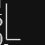


% Plotting
figure;

subplot(1,2,1)

Unrecognized function or variable 'rewardLabel'.

scatter(rewardLabel, ypred, 50, 'b', 'filled')
hold on
yline(threshold, 'r--', 'Threshold = 0.5');
xlabel('True reward (0/1)')
ylabel('Predicted value')
title(sprintf('Model fit (Acc = %.1f%%)', accuracy*100))
set(gca, 'Box', 'off', 'FontSize', 12)

subplot(1,2,2)
scatter(FR, rewardLabel, 50, 'b', 'filled')
hold on
xvals = linspace(min(FR), max(FR), 100)';
yhat = predict(mdl, xvals);
plot(xvals, yhat, 'r-', 'LineWidth', 2)
xlabel('Firing rate (Hz)')
ylabel('Rewarded trial (0 = no, 1 = yes)')
title(sprintf('Neuron %d - Linear regression fit', Neuron_ID))
set(gca,'Box','off','FontSize',12)

sgtitle(sprintf('Neuron %d - Linear regression prediction (Acc = %.1f%%)', Neuron_ID, accuracy*100))

% Stats
fprintf('\nNeuron %d\n', Neuron_ID);
fprintf('Classification accuracy: %.2f%%\n', accuracy*100);
disp(mdl)


#### Exercises

L7-E.1 - Check different neurons, can you find good ones?

### 2) Linear Regression: predict rewarded trials using multiple neurons

Linear regression allow us to use more than one predictor. Here, we are bassically doing the same, but now, you can select a neuron subset

% Each neuron contributes its firing rate as a predictor.
% The model learns a linear combination that best predicts reward outcome.

% Initial parameters
reward_col = 14;        % column with reward flag (1 = rewarded, 0 = not)
trial_start_col = 18;   % trial start time (s)
win = [0 2];            % analysis window (s) relative to trial start
Neuron_subset = 1:10 ;   % which neurons to include (e.g., first 10) (You can also select a specific group [1 10 25 111 128], for example
threshold = 0.5;        % classification threshold
SR = 20000;


% Data extraction

rewardLabel = Trials_Sync(:, reward_col);
nTrials = length(rewardLabel);
nNeurons = length(Neuron_subset);
FR = nan(nTrials, nNeurons);


for tr = 1:nTrials
    t0 = Trials_Sync(tr, trial_start_col)./SR;
    t1 = t0 + win(2);
    for n = 1:nNeurons
        col = Neuron_subset(n);
        spikeTimes = STMtx(~isnan(STMtx(:, col)), col);
        FR(tr,n) = sum(spikeTimes >= t0+win(1) & spikeTimes < t1) / diff(win);
    end
end

valid = ~isnan(sum(FR,2));
FR = FR(valid,:);
rewardLabel = rewardLabel(valid);

#### Questions

L7-Q.2 - The "for" loop used here is different from the one before. Why? what is happening?


% Fit linear model (Multiple neurons)
mdl = fitlm(FR, rewardLabel);

% Predict on the same data
ypred = predict(mdl, FR);

% Convert continuous predictions to binary (rewarded / not)
ypred_class = ypred > threshold;

% Compute accuracy
accuracy = mean(ypred_class == rewardLabel);


% Results
fprintf('\nLinear regression (multi-neuron)\n');
fprintf('Using %d neurons\n', nNeurons);
fprintf('Classification accuracy: %.2f%%\n', accuracy*100);

% Display model coefficients (which neurons matter most)
coef = mdl.Coefficients.Estimate(2:end);
[~, rankIdx] = sort(abs(coef), 'descend');

fprintf('\nTop contributing neurons (by weight magnitude):\n');
disp([Neuron_subset(rankIdx(:))' coef(rankIdx(:))])


% Plotting
figure;
subplot(1,2,1)
scatter(rewardLabel, ypred, 50, 'b', 'filled')
hold on
yline(threshold, 'b--', 'Threshold = 0.5');
xlabel('True reward (0/1)')
ylabel('Predicted value')
title(sprintf('Model fit (Acc = %.1f%%)', accuracy*100))
set(gca,'Box','off','FontSize',12)

subplot(1,2,2)
bar(Neuron_subset, coef)
xlabel('Neuron ID')
ylabel('Weight')
title('Neuron contribution (model coefficients)')
set(gca,'Box','off','FontSize',12)


#### Exercises

L7-E.2 - Try different number of neurons. What happens with the accuracy? what is your conclusion?

### 2) Linear Regression: Reward prediction using multiple neurons (Training and test)

The magic of using a training and a test group.

%% Linear Regression: Reward prediction using multiple neurons
% One training/test split — observe effect of adding more neurons

% Initial parameters

reward_col = 14;        % Reward flag (1 = rewarded, 0 = not)
trial_start_col = 18;   % Trial start time (s)
win = [0 2];            % Analysis window (s)
maxNeurons = 141;        % Test up to this many neurons
trainFraction = 0.5;    % Fraction of trials used for training
threshold = 0.5;        % Binary threshold
SR = 20000;

rng(1);  % for reproducibility


% Extracting and preparing data

rewardLabel = Trials_Sync(:, reward_col);
nTrials = length(rewardLabel);
nNeuronsTotal = size(STMtx, 2);

% Compute firing rate per neuron per trial

FR = nan(nTrials, nNeuronsTotal);
for tr = 1:nTrials
    t0 = Trials_Sync(tr, trial_start_col)./SR;
    t1 = t0 + win(2);
    for n = 1:nNeuronsTotal
        spikeTimes = STMtx(~isnan(STMtx(:,n)), n);
        FR(tr,n) = sum(spikeTimes >= t0+win(1) & spikeTimes < t1) / diff(win);
    end
end

valid = ~isnan(sum(FR,2));
FR = FR(valid,:);
rewardLabel = rewardLabel(valid);

% Split into training and test sets

nTrain = round(trainFraction * size(FR,1));
idx = randperm(size(FR,1));
trainIdx = idx(1:nTrain);
testIdx  = idx(nTrain+1:end);


% Analysing the effect of adding neurons

acc_train = nan(maxNeurons,1);
acc_test  = nan(maxNeurons,1);

for nUsed = 1:maxNeurons
    mdl = fitlm(FR(trainIdx, 1:nUsed), rewardLabel(trainIdx));

    % Predictions
    ytrain_pred = predict(mdl, FR(trainIdx, 1:nUsed)) > threshold;
    ytest_pred  = predict(mdl, FR(testIdx, 1:nUsed))  > threshold;

    % Accuracy
    acc_train(nUsed) = mean(ytrain_pred == rewardLabel(trainIdx));
    acc_test(nUsed)  = mean(ytest_pred  == rewardLabel(testIdx));
end
chanceLevel = mean(rewardLabel == mode(rewardLabel));

% Plotting

figure;
plot(1:maxNeurons, acc_train, '-o', 'LineWidth', 2, 'Color', [0.3 0.6 0.9])
hold on
plot(1:maxNeurons, acc_test, '-o', 'LineWidth', 2, 'Color', [0.9 0.4 0.4])
xlabel('Number of neurons used')
ylabel('Accuracy')
legend('Training', 'Testing', 'Location', 'best')
title('Effect of population size on reward prediction')
set(gca, 'Box', 'off', 'FontSize', 12)
ylim([0 1])
yline(chanceLevel, 'g--', 'LineWidth', 1.5, 'Label', 'Chance level', 'LabelHorizontalAlignment', 'left');


#### Questions

L7-Q.3 - What do you think is more or less the optimal number of neurons?

### 3) Linear Regression: Finding the best predictors

The magic of using a training and a test group.

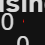

%% Linear Regression: Predict Reward from Firing Rates
% This version fits a linear model for comparison

% Parameters
reward_col = 14;     
trial_start_col = 18; 
%trial_end_col   = 19; 
win = [0 2];          
nFolds = 5;           
rng(1);
SR = 20000;

% Extract reward labels and firing rates as before
rewardLabel = Trials_Sync(:, reward_col);
nTrials = length(rewardLabel);
nNeurons = size(STMtx,2);
FR = nan(nTrials, nNeurons);

for tr = 1:nTrials
    t0 = Trials_Sync(tr, trial_start_col)./SR;
    t1 = t0 + win(2);
    for n = 1:nNeurons
        spikeTimes = STMtx(~isnan(STMtx(:, n)), n);
        FR(tr,n) = sum(spikeTimes >= t0+win(1) & spikeTimes < t1) / diff(win);
    end
end

valid = ~isnan(sum(FR,2)) & ~isnan(rewardLabel);
FR = FR(valid,:);
rewardLabel = rewardLabel(valid);

% Cross-validation
cv = cvpartition(rewardLabel, 'KFold', nFolds);
acc = nan(nFolds, nNeurons);

for fold = 1:nFolds
    trainIdx = training(cv, fold);
    testIdx  = test(cv, fold);

    Xtrain = FR(trainIdx, :);
    ytrain = rewardLabel(trainIdx);
    Xtest  = FR(testIdx, :);
    ytest  = rewardLabel(testIdx);

    for n = 1:nNeurons
        mdl = fitlm(Xtrain(:,n), ytrain);          % linear regression
        ypred = predict(mdl, Xtest(:,n));          % continuous output
        ypred_class = ypred > 0.5;                 % threshold to make binary
        acc(fold, n) = mean(ypred_class == ytest); % accuracy
    end
end

% Results
meanAcc = mean(acc, 1);
chanceLevel = mean(rewardLabel == mode(rewardLabel));

% Plotting
figure;
bar(meanAcc)
hold on
yline(chanceLevel, 'r--', 'LineWidth', 1.5)
xlabel('Neuron')
ylabel('Prediction Accuracy')
title('Reward Prediction using Linear Regression')
set(gca,'Box','off','FontSize',12)